# Exploring a ROS™ Network

[**Index**](matlab:closeNoPrompt(matlab.desktop.editor.getActive); edit ROSBasicsIndex)** | **[**Previous lesson**](matlab:closeNoPrompt(matlab.desktop.editor.getActive); edit HowROS)

*© *Copyright 2022 The MathWorks, Inc

ROS-Enbaled robots or systems will inherently run through a communication network. The most important thing to understand in order to interact with a ROS robot is what information is available in the existing network.

## Simulator

For the purpose of this tutorial we will use a virtual robot from the MATLAB® Robotics Playground that runs on ROS. in order to get the simulator started the following command is required (In MATLAB Online use middle-mouse-click to rotate the view):

myRobot = mlrosbot; myRobot.connect;
 

A new window with the virtual robot like the one below will appear.

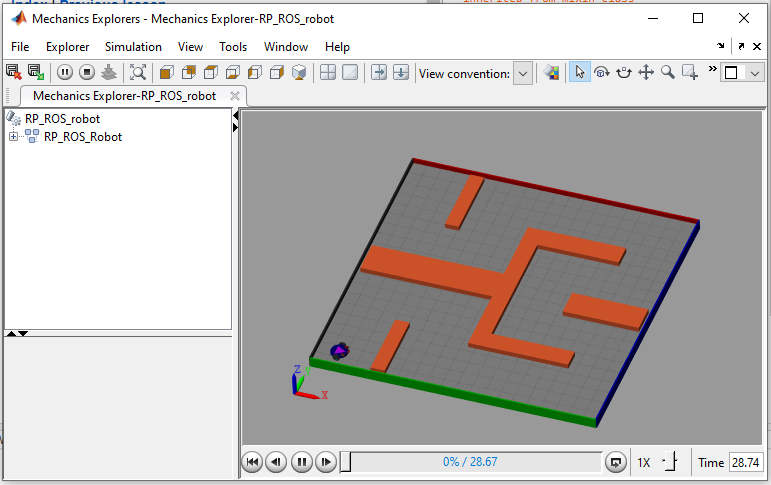

## Create a ROS2 Node

For the purposes of this tutorial we will work with ROS2, which is a specific variant of ROS. To be able to communicate with our simulated ROS-enabled robot.

To start a ROS2 node running from MATLAB to explore the ROS network you must use the "ros2node" function. an exmaple is shown is below where we create a ROS2 node and assign it to the variable "my_node"

my_node=ros2node("/my_node");  

## Explore Nodes

Use ROS2 commands to obtain a list of active nodes in the network:

ros2 node list  

There should be 3 ROS2 nodes active as seen below:

`/RP_ROS_robot_23992 ``% Main robot node`

`/RP_emergencyStop ``% Emergency Stop Service node`

`/my_node ``% MATLAB interface node`

## Explore Topics

Use a ROS2 command to obtain a list of topics that have been initialized in the ROS network:

ros2 topic list  

Topics are customized to each robot or system. In the case of our simulated robot, there is information corresponding to the motor in the wheels and three distance sensors.

`/RP_frontRange ``% Distance sensor data`

`/RP_leftMotor ``%  Motor speed data`

`/RP_leftRange ``% Distance sensor data`

`/RP_rightMotor ``% Motor speed data`

`/RP_rightRange ``% Distance sensor data`

`/parameter_events`

`/rosout`

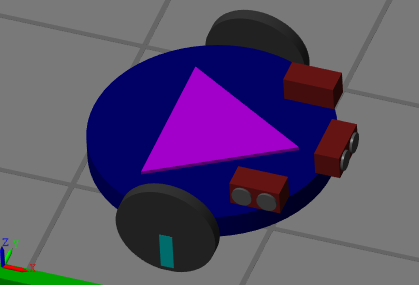

## Explore Services

Services and actions are are asynchronous algorithms that can be called upon at any given time by ROS nodes. Try exploring the services available for our robot using the following command:

ros2 service list  

Each node will have a set of default services to interact with its parameters as shown in the output. One dedicated service for the simualted robot is an emergencey stop function called "/RP_emergencyStop". 

## Close ROS2 Node and Stop Simulator

clear my_node;
myRobot.disconnect;  

[**Next lesson: Messages and Topics**](matlab:closeNoPrompt(matlab.desktop.editor.getActive); edit ROSMessagesTopics)